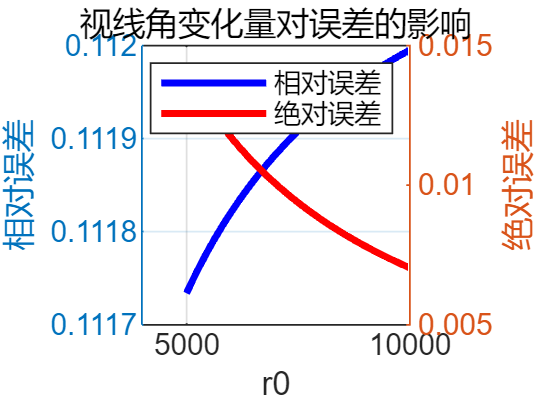

% 参数设置
r0 = linspace(5000, 10000, 100); % 视线角变化量范围（度）
qr_deg = -55;
qr = deg2rad(qr_deg); % 转换为弧度
r0_mid = r0;
theta0_deg = 15; % 初始弹道倾角（度）
theta0 = deg2rad(theta0_deg);
N = 3; % 导航系数
v = 300; % 导弹速度（m/s）
q0 = 0; % 初始视线角（弧度）
% 预分配存储
b_theory = zeros(size(r0));
b_actual = zeros(size(r0));
absolute_error = zeros(size(r0));
relative_error = zeros(size(r0));
% 对每个qr计算理论b和实际b的误差
for i = 1:length(r0)
% 期望终端角度θf = q0 + qr（弧度）
theta_f = q0 + qr;
% 理论飞行时间
tf_theory = r0(i) / v;
% 理论b计算（公式13）
numerator = N*q0 - theta0 - (N-1)*theta_f;
b_theory(i) = numerator / tf_theory;
% 通过优化找到实际b使得θf_real = theta_f
options = optimset('TolX', 1e-6, 'Display', 'off');
b_actual(i) = fzero(@(b) compute_theta_error(b, N, v, r0(i), q0, theta0, theta_f), b_theory(i), options);
% 计算绝对误差
absolute_error(i) = b_actual(i) - b_theory(i);
% 计算相对误差
relative_error(i) = absolute_error(i) / abs(b_theory(i));
end
% 绘制结果
absolute_error_mid = abs(absolute_error);
figure('Color', 'white');
yyaxis left;
plot(r0, abs(relative_error), 'LineWidth', 2, 'DisplayName', '相对误差', 'Color', 'b');
ylabel('相对误差');
title('视线角变化量对误差的影响');
grid on;
yyaxis right;
plot(r0, abs(absolute_error), 'LineWidth', 2, 'DisplayName', '绝对误差', 'Color', 'r');
ylabel('绝对误差');
% 添加图例
legend show;
xlabel('r0');

function error = compute_theta_error(b, N, v, r0, q0, theta0, theta_f)
% 导弹运动方程
function dydt = dynamics(~, y)
r = y(1);
q = y(2);
theta = y(3);
eta = theta - q;
q_dot = -v * sin(eta) / r;
theta_dot = N * q_dot + b;
r_dot = -v * cos(eta);
dydt = [r_dot; q_dot; theta_dot];
end
% 事件函数：当r <= 1m时停止
function [value, isterminal, direction] = stop_event(~, y)
value = y(1) - 1;
isterminal = 1;
direction = -1;
end
% 初始条件
y0 = [r0; q0; theta0];
tspan = [0, 1000]; % 足够长的仿真时间
% 数值积分
options = odeset('Events', @stop_event, 'RelTol', 1e-6);
[~, y] = ode45(@dynamics, tspan, y0, options);
if isempty(y)
error = Inf;
else
theta_real = y(end, 3);
error = theta_real - theta_f; % 终端角度误差
end
end 



